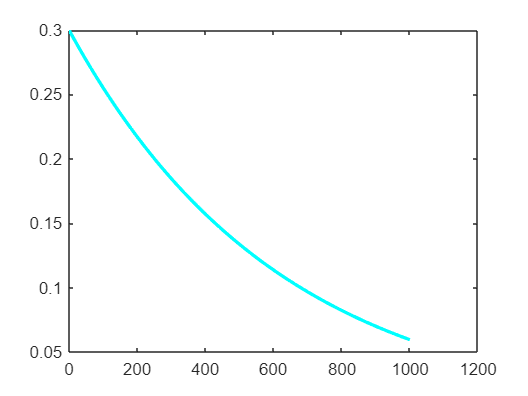

clear, clc, close all
k1 = 1.6e-3;

f = @(t,N) -N*k1;

xrange = [0,1000];

yinitial = 0.3;

[t,N] = EulerSolver(f,xrange,yinitial,77);
plot(t,N,'c-','linewidth',2)

function [x,y] = EulerSolver(f,xrange,yinitial, numstep)
    x(1) = xrange(1); y(1) = yinitial;
    step_size = (xrange(2)-xrange(1))/numstep;
    
    for j = 1:numstep
        gradient = f(x(j),y(j));
        y(j+1) = y(j)+gradient*step_size;
        x(j+1) = x(j)+step_size;
    end
end